# Labolatorium 3 - Modulacja amplitudy, Demodulacja dla AM, DSB AM i SSB AM 

Definiujemy nośną jako $c=A_c \textrm{∙}\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi f_c t\right)$ oraz sygnały modulujące jako  $m_1 =A_m \textrm{∙}\mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi f_m t\right)$  m2 - sygnał prostokątny (przeskok fazy, K<-1) $m_3 =A_m \textrm{∙}\sum_{i=1}^{10} \mathrm{c}\mathrm{o}\mathrm{s}\left(2\pi it\right)$

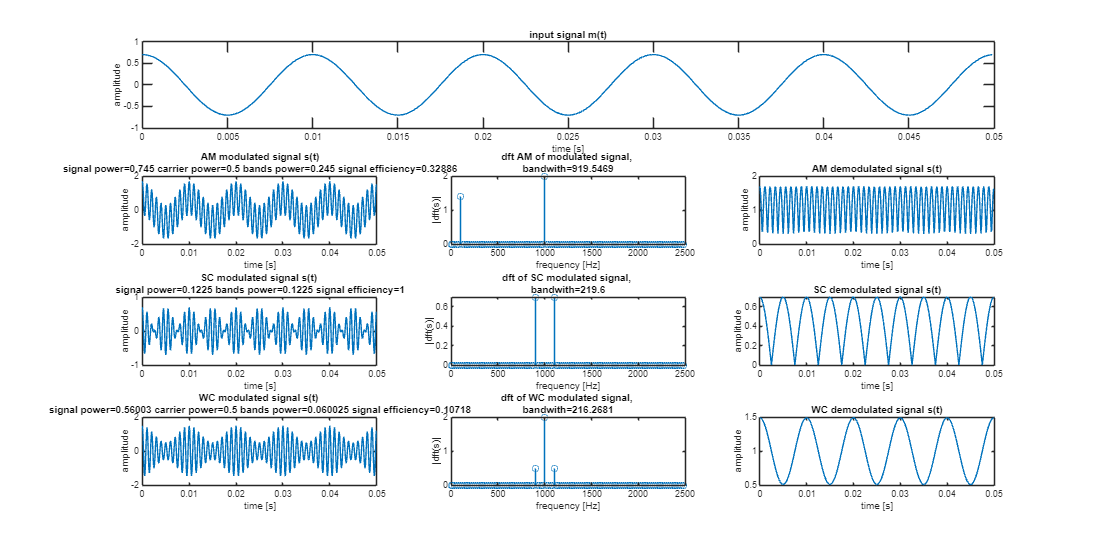

%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.7;
fm = 100;



%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);


%---------------------definicja m1-----------------------------


m1 = Am *cos(2*pi*fm*t);


calculate(c, fs, Am, Ac, t, m1)

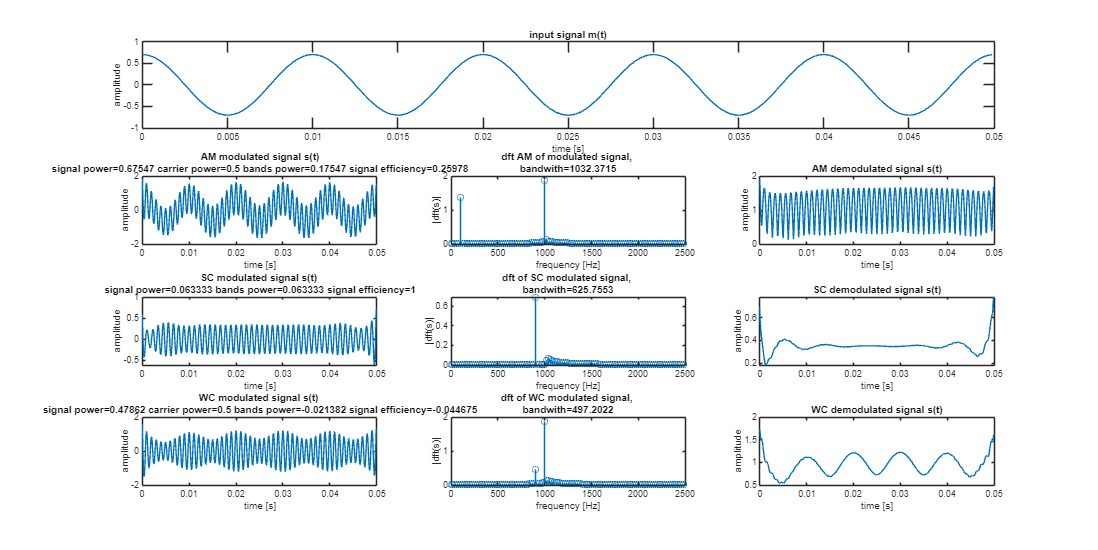

calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m1)

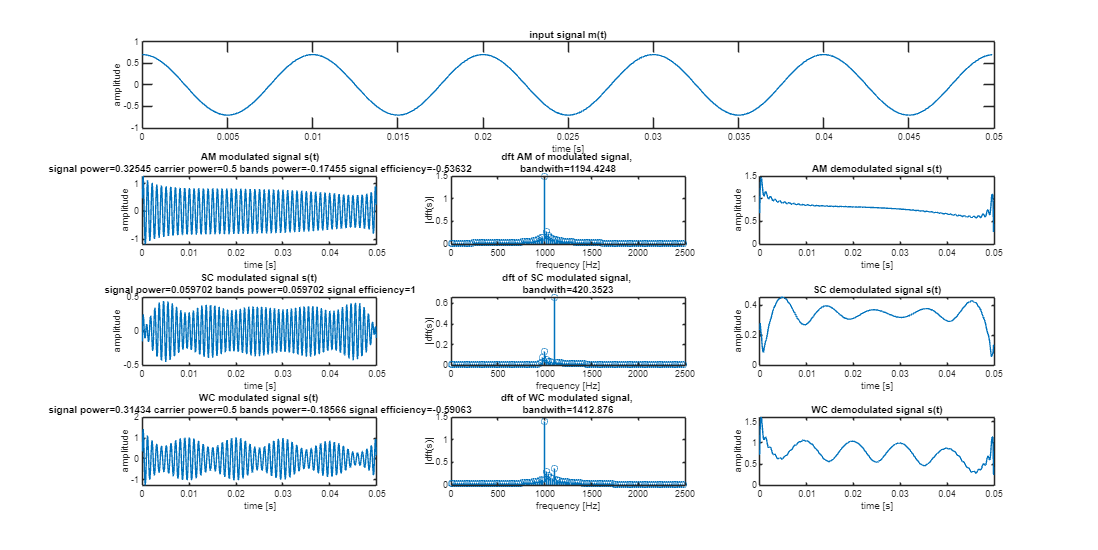

calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m1)

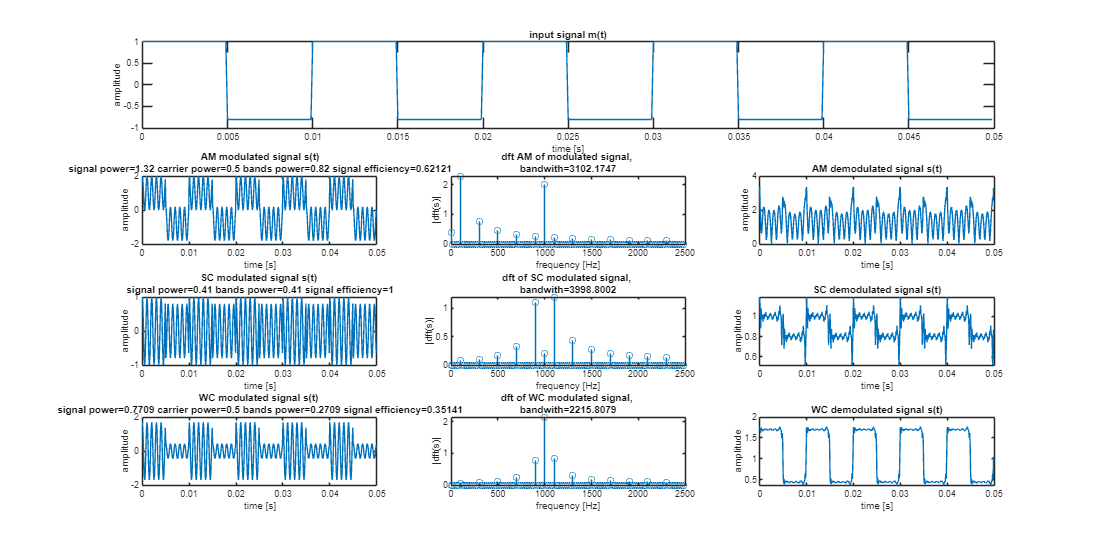


%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.7;
fm = 100;
K = -0.8;



%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);


%---------------------definicja m2-----------------------------

one_cycle = [ones(1, length(t)/10), K * ones(1, length(t)/10)];
m2 = [one_cycle, one_cycle, one_cycle, one_cycle, one_cycle];

calculate(c, fs, Am, Ac, t, m2)

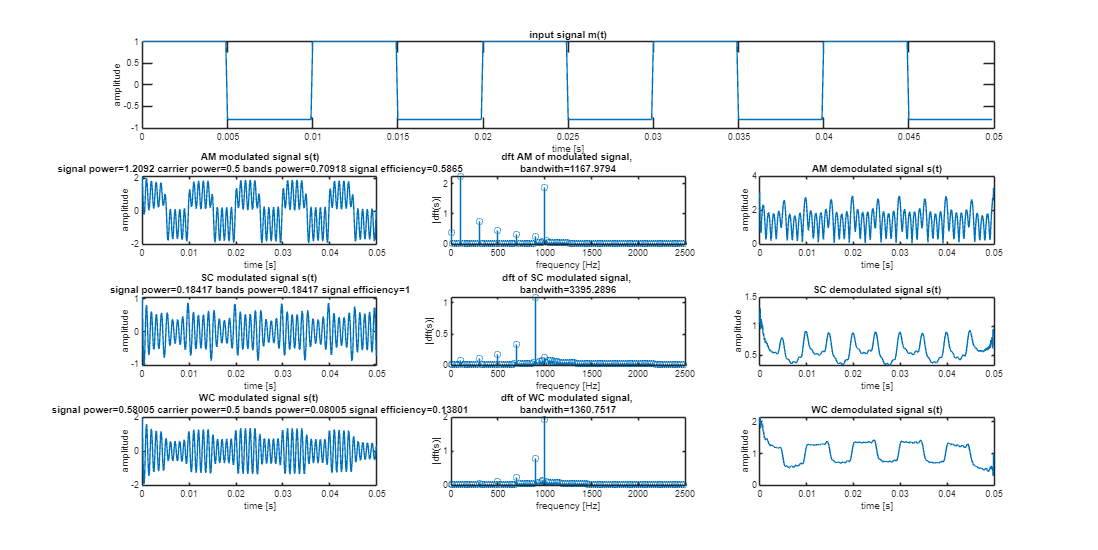

calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m2)

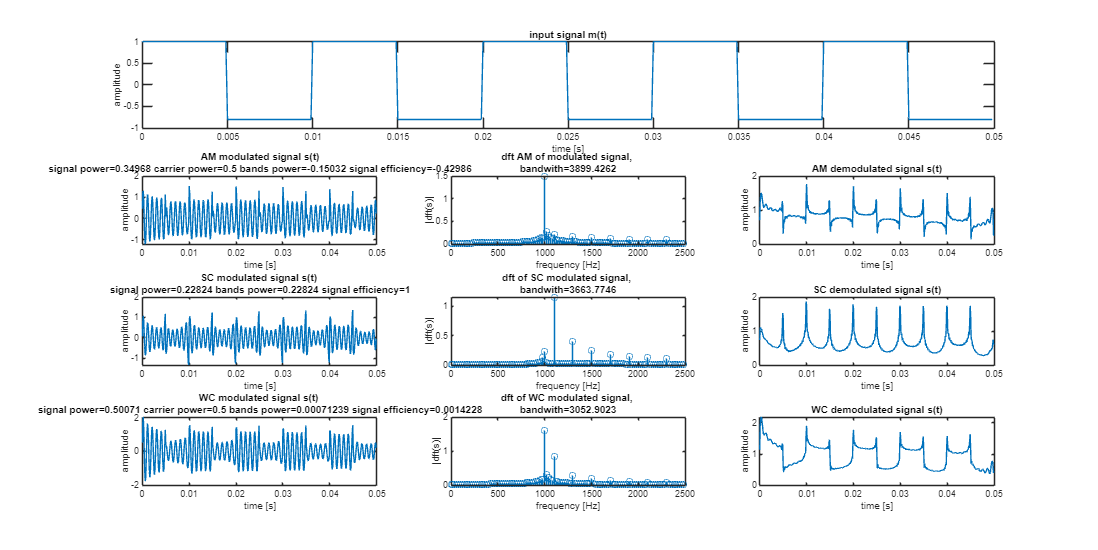

calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m2)

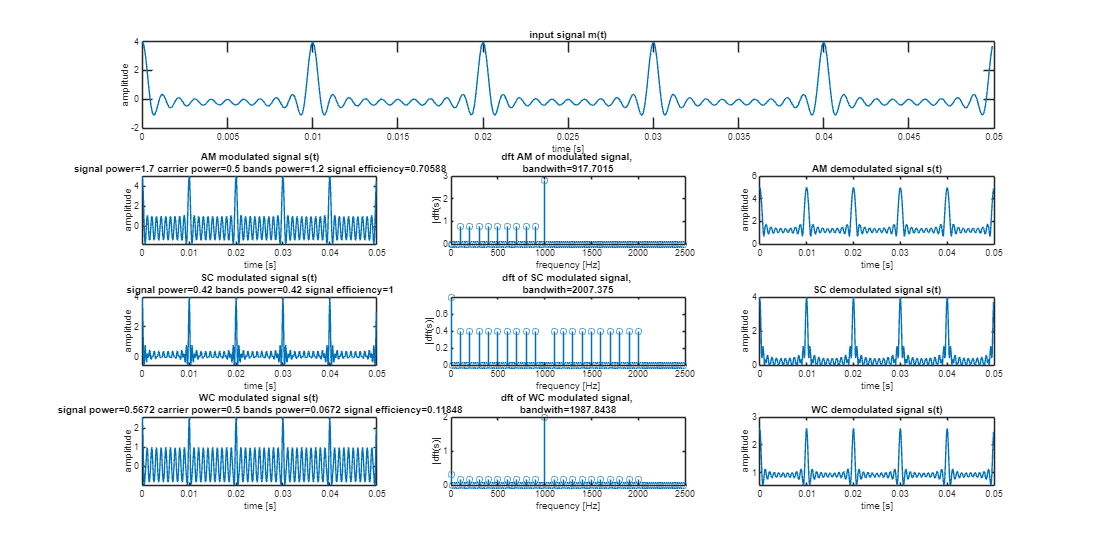



%---------------------definicje parametrów-----------------------------
Ac = 1;
fc = 1000; %Hz
Am = 0.4;
fm = 100;



%--------------------definicja nośnej------------------------------
tmax = 5/fm; % 5 cycles in ms
fs = fc * 10;
t  = 0:1/fs:tmax-(1/fs);
c = Ac * cos(2*pi*fc*t);


%---------------------definicja m3-----------------------------
m3 = 0;
for i = 1:10
    m3 = m3 + Am * cos(2*pi*fm*i*t);
end

calculate(c, fs, Am, Ac, t, m3)

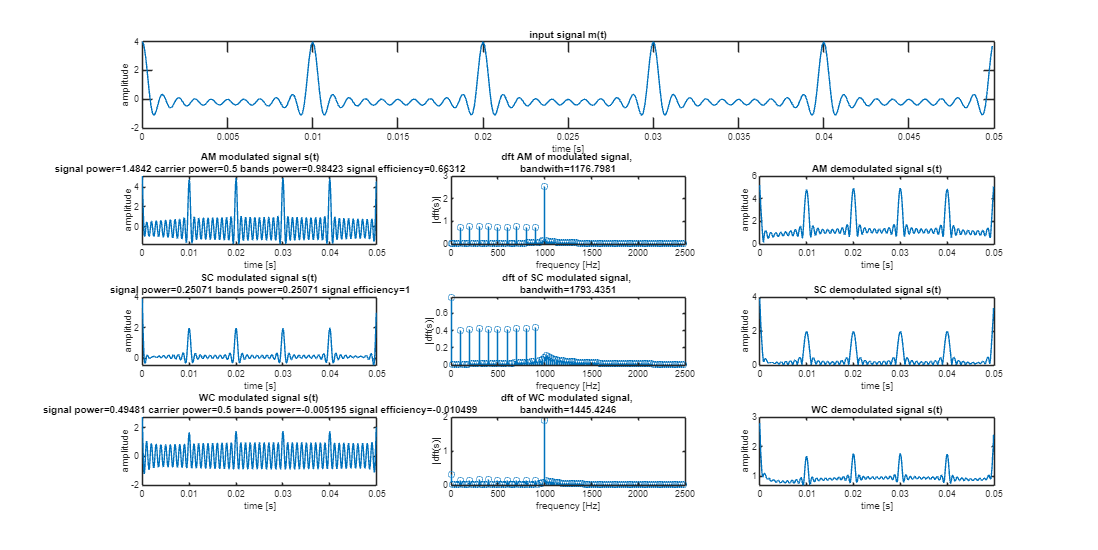

calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m3)

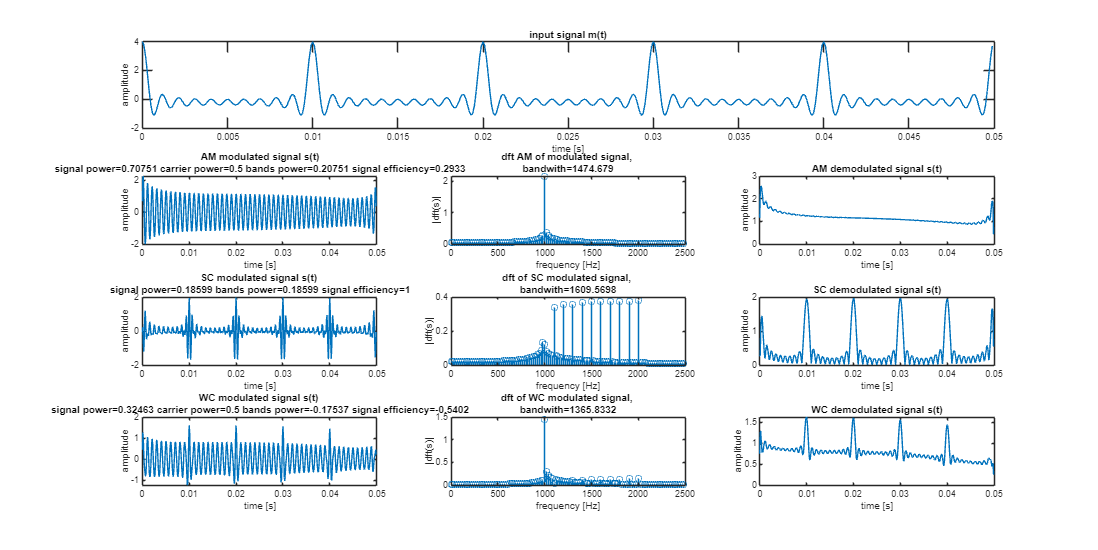

calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m3)

function X = calculate(c, fs, Am, Ac, t, m1)

    c_rms = rms(c)^2;
    k = Am / Ac;

    s1_m1 = c + m1;
    s1_m1_fft = fft(s1_m1);
    s1_m1_BW = obw(s1_m1, fs);
    s1_m1_rms = rms(s1_m1)^2;
    s1_m1_bands_rms = s1_m1_rms - c_rms;
    s1_m1_eff = s1_m1_bands_rms / s1_m1_rms;
    s1_m1_demodulated = abs(hilbert(s1_m1));

    s2_m1 = c .* m1;
    s2_m1_fft = fft(s2_m1);
    s2_m1_BW = obw(s2_m1, fs);
    s2_m1_rms = rms(s2_m1)^2;
    s2_m1_bands_rms = s2_m1_rms;
    s2_m1_eff = s2_m1_bands_rms / s2_m1_rms;
    s2_m1_demodulated = abs(hilbert(s2_m1));

    
    
    s3_m1 = c .* (1 + m1*k);
    s3_m1_fft = fft(s3_m1);
    s3_m1_BW = obw(s3_m1, fs);
    s3_m1_rms = rms(s3_m1)^2;
    s3_m1_bands_rms = s3_m1_rms - c_rms;
    s3_m1_eff = s3_m1_bands_rms / s3_m1_rms;
    s3_m1_demodulated = abs(hilbert(s3_m1));

    
    
    fig = figure;
    fig.Position = [0, 0, 2000, 1000];
    subplot(4, 3, [1,2,3])
    plot(t, m1)
    title('input signal m(t)')
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 4)
    plot(t, s1_m1)
    title(['AM modulated signal s(t)', newline, 'signal power=', num2str(s1_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m1_bands_rms), ' signal efficiency=', num2str(s1_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,5)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
    title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,6)
    plot(t, s1_m1_demodulated)
    title(['AM demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 7)
    plot(t, s2_m1)
    title(['SC modulated signal s(t) ', newline, 'signal power=', num2str(s2_m1_rms),' bands power=', num2str(s2_m1_bands_rms), ' signal efficiency=', num2str(s2_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,8)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,9)
    plot(t, s2_m1_demodulated)
    title(['SC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 10)
    plot(t, s3_m1)
    title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m1_bands_rms), ' signal efficiency=', num2str(s3_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,11)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,12)
    plot(t, s3_m1_demodulated)
    title(['WC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
end



function X = calculate_SSB_LSB(fc, c, fs, Am, Ac, t, m1)

    c_rms = rms(c)^2;
    k = Am / Ac;

    s1_m1 = c + m1;
    s1_m1 = lowpass(s1_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s1_m1_fft = fft(s1_m1);
    s1_m1_BW = obw(s1_m1, fs);
    s1_m1_rms = rms(s1_m1)^2;
    s1_m1_bands_rms = s1_m1_rms - c_rms;
    s1_m1_eff = s1_m1_bands_rms / s1_m1_rms;
    s1_m1_demodulated = abs(hilbert(s1_m1));

    s2_m1 = c .* m1;
    s2_m1 = lowpass(s2_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s2_m1_fft = fft(s2_m1);
    s2_m1_BW = obw(s2_m1, fs);
    s2_m1_rms = rms(s2_m1)^2;
    s2_m1_bands_rms = s2_m1_rms;
    s2_m1_eff = s2_m1_bands_rms / s2_m1_rms;
    s2_m1_demodulated = abs(hilbert(s2_m1));

    
    
    s3_m1 = c .* (1 + m1*k);
    s3_m1 = lowpass(s3_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s3_m1_fft = fft(s3_m1);
    s3_m1_BW = obw(s3_m1, fs);
    s3_m1_rms = rms(s3_m1)^2;
    s3_m1_bands_rms = s3_m1_rms - c_rms;
    s3_m1_eff = s3_m1_bands_rms / s3_m1_rms;
    s3_m1_demodulated = abs(hilbert(s3_m1));

    
    
    fig = figure;
    fig.Position = [0, 0, 2000, 1000];
    subplot(4, 3, [1,2,3])
    plot(t, m1)
    title('input signal m(t)')
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 4)
    plot(t, s1_m1)
    title(['AM modulated signal s(t)', newline, 'signal power=', num2str(s1_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m1_bands_rms), ' signal efficiency=', num2str(s1_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,5)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
    title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,6)
    plot(t, s1_m1_demodulated)
    title(['AM demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 7)
    plot(t, s2_m1)
    title(['SC modulated signal s(t) ', newline, 'signal power=', num2str(s2_m1_rms),' bands power=', num2str(s2_m1_bands_rms), ' signal efficiency=', num2str(s2_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,8)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,9)
    plot(t, s2_m1_demodulated)
    title(['SC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 10)
    plot(t, s3_m1)
    title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m1_bands_rms), ' signal efficiency=', num2str(s3_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,11)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,12)
    plot(t, s3_m1_demodulated)
    title(['WC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
end


function X = calculate_SSB_MSB(fc, c, fs, Am, Ac, t, m1)

    c_rms = rms(c)^2;
    k = Am / Ac;

    s1_m1 = c + m1;
    s1_m1 = highpass(s1_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s1_m1_fft = fft(s1_m1);
    s1_m1_BW = obw(s1_m1, fs);
    s1_m1_rms = rms(s1_m1)^2;
    s1_m1_bands_rms = s1_m1_rms - c_rms;
    s1_m1_eff = s1_m1_bands_rms / s1_m1_rms;
    s1_m1_demodulated = abs(hilbert(s1_m1));

    s2_m1 = c .* m1;
    s2_m1 = highpass(s2_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s2_m1_fft = fft(s2_m1);
    s2_m1_BW = obw(s2_m1, fs);
    s2_m1_rms = rms(s2_m1)^2;
    s2_m1_bands_rms = s2_m1_rms;
    s2_m1_eff = s2_m1_bands_rms / s2_m1_rms;
    s2_m1_demodulated = abs(hilbert(s2_m1));

    
    
    s3_m1 = c .* (1 + m1*k);
    s3_m1 = highpass(s3_m1,fc,fs,ImpulseResponse="iir",Steepness=0.95);
    s3_m1_fft = fft(s3_m1);
    s3_m1_BW = obw(s3_m1, fs);
    s3_m1_rms = rms(s3_m1)^2;
    s3_m1_bands_rms = s3_m1_rms - c_rms;
    s3_m1_eff = s3_m1_bands_rms / s3_m1_rms;
    s3_m1_demodulated = abs(hilbert(s3_m1));

    
    
    fig = figure;
    fig.Position = [0, 0, 2000, 1000];
    subplot(4, 3, [1,2,3])
    plot(t, m1)
    title('input signal m(t)')
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 4)
    plot(t, s1_m1)
    title(['AM modulated signal s(t)', newline, 'signal power=', num2str(s1_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s1_m1_bands_rms), ' signal efficiency=', num2str(s1_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,5)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s1_m1_fft(1:length(t)/4)/length(k)))
    title(['dft AM of modulated signal, ',newline, 'bandwith=', num2str(s1_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,6)
    plot(t, s1_m1_demodulated)
    title(['AM demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 7)
    plot(t, s2_m1)
    title(['SC modulated signal s(t) ', newline, 'signal power=', num2str(s2_m1_rms),' bands power=', num2str(s2_m1_bands_rms), ' signal efficiency=', num2str(s2_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,8)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s2_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of SC modulated signal, ',newline, 'bandwith=', num2str(s2_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,9)
    plot(t, s2_m1_demodulated)
    title(['SC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4, 3, 10)
    plot(t, s3_m1)
    title(['WC modulated signal s(t) ',newline, 'signal power=', num2str(s3_m1_rms), ' carrier power=', num2str(c_rms), ' bands power=', num2str(s3_m1_bands_rms), ' signal efficiency=', num2str(s3_m1_eff)])
    xlabel('time [s]')
    ylabel('amplitude')
    subplot(4,3,11)
    k = 0:(length(t)/4)-1;
    stem(k*0.25*fs/length(k), abs(s3_m1_fft(1:length(t)/4)/length(k)))
    title(['dft of WC modulated signal, ',newline, 'bandwith=', num2str(s3_m1_BW)])
    xlabel('frequency [Hz]')
    ylabel('|dft(s)|')
    subplot(4,3,12)
    plot(t, s3_m1_demodulated)
    title(['WC demodulated signal s(t)'])
    xlabel('time [s]')
    ylabel('amplitude')
end

